# Lab 3 

Ali Saeizadeh

810196477

## Lab 3_1

### 1.

clear all
load('lp_filter.mat')
N = 4096;
seq = randn(N,1);
filter_out = conv(seq, lp_filter,"same");

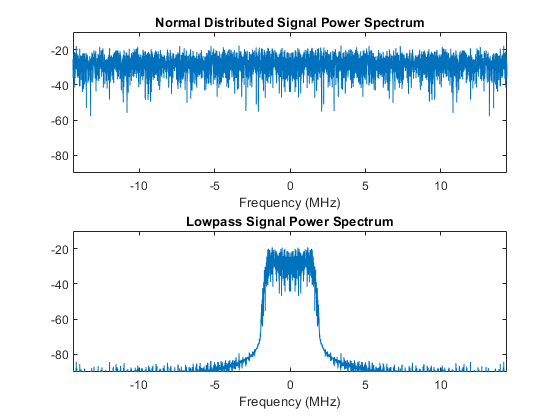

fs = 28.8e6;
n_fft = 4096;
[s, freq] = spectral_dens(seq,fs,n_fft);
subplot(2,1,1)
plot(freq/1e6, s)
title('Normal Distributed Signal Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])
[s, freq] = spectral_dens(filter_out,fs,n_fft);
subplot(2,1,2)
plot(freq/1e6, s)
title('Lowpass Signal Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])

time_power_original = power_time(seq)

time_power_original = 0.9851

time_power_filter_out = power_time(filter_out)

time_power_filter_out = 0.1074

power_ration = time_power_filter_out/time_power_original

power_ration = 0.1090

bw_noise = noisebw(lp_filter,1,length(lp_filter),fs)

bw_noise = 3.3081e+06

bw_ratio = bw_noise/fs

bw_ratio = 0.1149

با توجه به اینکه سیگنال از نوع نویز سفید استو توان آن برابر با یک است و انرژی آن در طیف بصورت یکسان پخش شده بنابراین میتوان گفت رابطه زیر برقرار است.


$$\frac{P_{filtered}}{P_{N}} \approx \frac{BW_{filtered}}{BW_N}$$


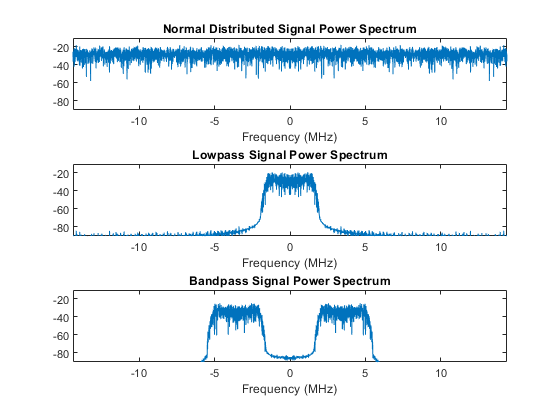

figure
[s, freq] = spectral_dens(seq,fs,n_fft);
subplot(3,1,1)
plot(freq/1e6, s)
title('Normal Distributed Signal Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])
[s, freq] = spectral_dens(filter_out,fs,n_fft);
subplot(3,1,2)
plot(freq/1e6, s)
title('Lowpass Signal Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])
fc = 3.56e6;
mod_sig = modulation(filter_out,fc,fs);
[s, freq] = spectral_dens(mod_sig,fs,n_fft);
subplot(3,1,3)
plot(freq/1e6, s)
title('Bandpass Signal Power Spectrum')
xlabel('Frequency (MHz)')
ylim([-90 -10])
xlim([-fs/2/1e6 fs/2/1e6])


time_power_original = power_time(seq)

time_power_original = 0.9851

time_power_filter_out = power_time(filter_out)

time_power_filter_out = 0.1074

time_power_mod = power_time(mod_sig)

time_power_mod = 0.0537

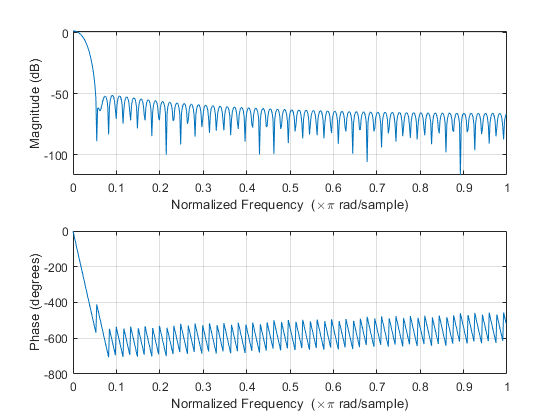

lp_filter_07 = fir1(120,[1/fs (0.7e6)/fs]);
freqz(lp_filter_07)

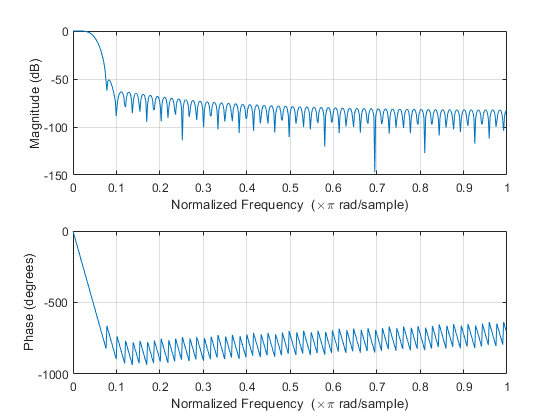

lp_filter_14 = fir1(120,[1/fs (1.4e6)/fs]);
freqz(lp_filter_14)

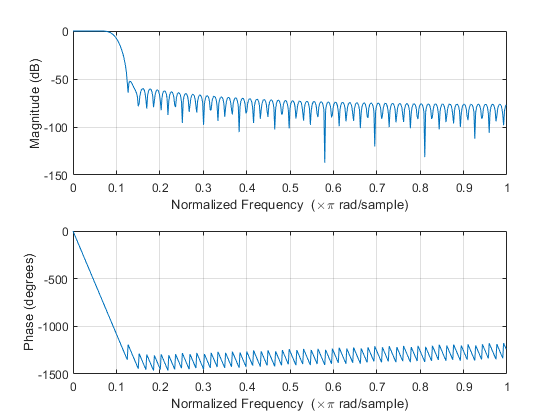

lp_filter_28 = fir1(120,[1/fs (2.8e6)/fs]);
freqz(lp_filter_28)

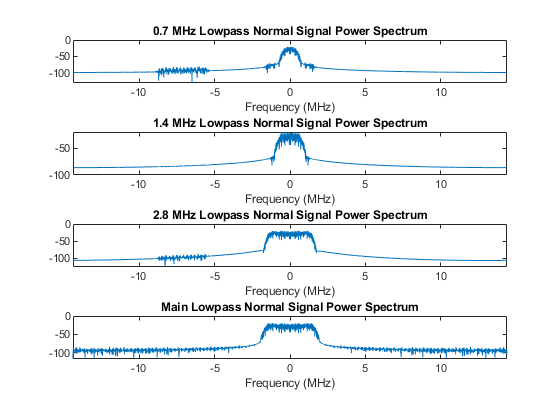

filtered_07 = demodulation(mod_sig, fc, fs, lp_filter_07);
filtered_14 = demodulation(mod_sig, fc, fs, lp_filter_14);
filtered_28 = demodulation(mod_sig, fc, fs, lp_filter_28);
figure
[s, freq] = spectral_dens(filtered_07,fs,n_fft);
subplot(4,1,1)
plot(freq/1e6, s)
title('0.7 MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
[s, freq] = spectral_dens(filtered_14,fs,n_fft);
subplot(4,1,2)
plot(freq/1e6, s)
title('1.4 MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
[s, freq] = spectral_dens(filtered_28,fs,n_fft);
subplot(4,1,3)
plot(freq/1e6, s)
title('2.8 MHz Lowpass Normal Signal Power Spectrum')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])
[s, freq] = spectral_dens(filter_out,fs,n_fft);
subplot(4,1,4)
plot(freq/1e6, s)
title('Main Lowpass Normal Signal Power Spectrum')
xlabel('Frequency (MHz)')
xlim([-fs/2/1e6 fs/2/1e6])


x_baseband_power = power_time(filter_out)

x_baseband_power = 0.1074

x_baseband_0p7_power = (power_time(filtered_07))

x_baseband_0p7_power = 0.0203

x_baseband_1p4_power = (power_time(filtered_14))

x_baseband_1p4_power = 0.0389

x_baseband_2p8_power = (power_time(filtered_28))

x_baseband_2p8_power = 0.0870

همانطور که در شکل های مشخص است با افزایش پهنای باند فیلتر به پهنای باند سیگنال اصلی سیگنال خروجی بیشتر به سیگنال اولیه شباهت دارد .

در مورد انرژی آن هم با افزایش پهنای باند فیلتر المان های فرکانسی بیشتری از فیلتر عبور میکنند بنابراین انرژی با افزایش پهنای باند افزایش پیدا میکند زیرا هنوز پهنای باند فیلتر از پهنای باند سیگنال کوچکتر است

اما این رابطه مانند بخش الف خطی نیست زیرا انرژی سیگنال سیگنال بصورت یکسان در طیف خود پخش نشده است. 